# **CS 5487 Programming Assignment 1 part1**

## **(a) Implementation of 5 algorithms can be found in the seperated function matlab files**

- Transformation Transform.m

- least-squares (LS) LS.m

- regularized LS (RLS) RLS.m

- L1-regularized LS (LASSO) LASSO.m

- robust regression (RR) RR.m

- Bayesian regression (BR) BR.m

## **(b) Training, Estimation and Plot**

- calMeanSquaredErr.m

- chosingHyper.m (assume we know real outputs of testset, i.e. sampy -> based on mean-squared error)

load("PA-1-data-matlab/poly_data.mat");
%K-order polynomial
K = 5;
%transformation of features
phi = Transform(sampx, K);

#### training

For hyperparameters, we select it by hand, by which I mean I implement chosingHyper function in which calMeanSquaredErr on the test set is envoked to get comparison.  (in reality, the real output for test set is not known, like mentioned in part3).

%training
theta_LS = LS(phi, sampy);

lambda_RLS = choosingHyper(0.01, 1, 0.01, 5, polyx, polyy, sampx, sampy, "RLS", "poly");
theta_RLS = RLS(phi, sampy, lambda_RLS);

lambda_LASSO = choosingHyper(0.001, 2, 0.001, 5, polyx, polyy, sampx, sampy, "LASSO", "poly");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

theta_LASSO = LASSO(phi, sampy, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



theta_RR = RR(phi, sampy);

Optimal solution found.




alpha_BR = choosingHyper(5, 20, 0.1, 5, polyx, polyy, sampx, sampy, "BR", "poly");
[mean_BR, cov_BR] = BR(phi, sampy, alpha_BR, 5);


#### prediction

%prediction
phi_test = Transform(polyx, K);
f_LS = phi_test' * theta_LS;
f_RLS = phi_test' * theta_RLS;
f_LASSO = phi_test' * theta_LASSO;
f_RR = phi_test' * theta_RR;
f_BR = phi_test' * mean_BR;
f_BR_var = phi_test' * cov_BR * phi_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));


#### plot

%plot the real function
x_function = -2:0.01:2;
phi_function = Transform(x_function, K);
y_function = phi_function' * thtrue;
plot(x_function, y_function, "r");

%plot the Regression
y_regression_full = [f_LS, f_RLS, f_LASSO, f_RR, f_BR, f_BR_pos, f_BR_neg];

hold on
scatter(polyx, y_regression_full, 5 ,"filled");

title("Original Function & Regression");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR", "BR+", "BR-"]);
hold off

#### mean-squared error

err = zeros(size(y_regression_full, 2)-2, 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_full,2)-2
    err(i) = calMeanSquaredErr(y_regression_full(:,i), polyy);
end
b = bar(errlabel, err);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

## **(c) Reduce training size**

As the training size is n=50, we choose the reduced size count = [40, 30, 20, 10, 5], roughly 80%, 60%, 40%, 20%, 10%. For each size, we run 5 trials with diﬀerent random subsets, and take the average error. We also select the best hyperparameters.

#### training

%we first save the trained parameters in previous sections as later they
%will be overwrite. 
theta_full = [theta_LS, theta_RLS, theta_LASSO, theta_RR, mean_BR, cov_BR];
mean_BR_full = mean_BR;
cov_BR_full = cov_BR;
%warning: run it twice will cause error since below
%update the dimension of these parameters

% to make fixed outcome, we use random seeds
seed = RandStream('mlfg6331_64');
count = [40, 30, 20, 10, 5];
theta_LS = zeros(K+1, K);
theta_RLS = zeros(K+1, 5);
theta_LASSO = zeros(K+1, 5);
theta_RR = zeros(K+1, 5);
mean_BR = zeros(K+1, 5);
cov_BR = zeros([size(cov_BR), 5]);
for i=1:5
    temp = [sampx; sampy'];
    temp = datasample(seed,temp,count(i),2,"Replace", false);
    temp_x = temp(1, 1:size(temp,2));
    temp_phi = Transform(temp_x, K);
    temp_y = temp(end, 1:size(temp,2))';
    lambda_RLS = choosingHyper(1, 200, 1, 5, polyx, polyy, temp_x, temp_y, "RLS", "poly");
    lambda_LASSO = choosingHyper(1, 200, 1, 5, polyx, polyy, temp_x, temp_y, "LASSO", "poly");
    alpha_BR = choosingHyper(0.1, 10, 0.1, 5, polyx, polyy, temp_x, temp_y, "BR", "poly");
    theta_LS(:,i) = LS(temp_phi, temp_y);
    theta_RLS(:,i) = RLS(temp_phi, temp_y, lambda_RLS);
    theta_LASSO(:,i) = LASSO(temp_phi, temp_y, lambda_LASSO);
    theta_RR(:,i) = RR(temp_phi, temp_y);
    [mean_BR(:,i), cov_BR(:,:,i)] = BR(temp_phi, temp_y, alpha_BR, 5);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.



#### prediction

%prediction
f_LS = phi_test' * theta_LS;
f_RLS = phi_test' * theta_RLS;
f_LASSO = phi_test' * theta_LASSO;
f_RR = phi_test' * theta_RR;
f_BR = phi_test' * mean_BR;

% [~,~,np] = size(cov_BR);
% f_BR_var = zeros([size(phi_test' * phi_test), np]);
% for i=1:np
%     f_BR_var(:,:,i) = phi_test' * cov_BR(:,:,i) * phi_test;
% end
% f_BR_pos = zeros(size(f_BR));
% f_BR_neg = zeros(size(f_BR));
% for i=1:5 
%     f_BR_pos(:,i) = f_BR(i) + sqrt(diag(squeeze(f_BR_var(:,:,i))));
%     f_BR_neg(:,i) = f_BR(i) - sqrt(diag(squeeze(f_BR_var(:,:,i))));
% end

#### plot

y_regression_reduced = cat(3, f_LS, f_RLS, f_LASSO, f_RR, f_BR);
y_regression_reduced = permute(y_regression_reduced, [1,3,2]);

%plot the real function
plot(x_function, y_function, "r");
%plot the Regression n=40
hold on
scatter(polyx, y_regression_reduced(:,:,1), 30 );

title("Original Function & Regression N = 40 (80%)");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off


%plot the real function
plot(x_function, y_function, "r");
%plot the Regression n=30
hold on
scatter(polyx, y_regression_reduced(:,:,2), 30 );

title("Original Function & Regression N = 30 (60%)");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

%plot the real function
plot(x_function, y_function, "r");
%plot the Regression n=20
hold on
scatter(polyx, y_regression_reduced(:,:,3), 30 );

title("Original Function & Regression N = 20 (40%)");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

%plot the real function
plot(x_function, y_function, "r");
%plot the Regression n=10
hold on
scatter(polyx, y_regression_reduced(:,:,4), 30);

title("Original Function & Regression N = 10 (20%)");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
hold off

%plot the real function
plot(x_function, y_function, "r");
%plot the Regression n=5
hold on
scatter(polyx, y_regression_reduced(:,:,5), 30 );

title("Original Function & Regression N = 5 (10%)");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR"]);
ylim([-200 200]);
hold off

#### mean-squared error

%Average over 5 trials
trials = 5;
theta_reduced = [theta_LS, theta_RLS, theta_LASSO, theta_RR];
mean_BR_reduced = mean_BR;
cov_BR_reduced = cov_BR; 
%first
err_reduced = zeros(size(y_regression_reduced, 2), 5);
for j = 1:5
    for i = 1:size(y_regression_reduced,2)
        err_reduced(i, j) = calMeanSquaredErr(y_regression_reduced(:,i, j), polyy);
    end
end

y_regression_reduced = reshape(y_regression_reduced, [100 5 5 1]);
%warning: run this section twice will cause error as y_regression_reduced's
%dimension is updated later

%second and third
for k = 1:trials-1
    %train
    for i=1:5
        temp = [sampx; sampy'];
        temp = datasample(seed,temp,count(i),2,"Replace", false);
        temp_x = temp(1, 1:size(temp,2));
        temp_phi = Transform(temp_x, K);
        temp_y = temp(end, 1:size(temp,2))';

        lambda_RLS = choosingHyper(1, 200, 1, 5, polyx, polyy, temp_x, temp_y, "RLS", "poly");
        lambda_LASSO = choosingHyper(1, 200, 1, 5, polyx, polyy, temp_x, temp_y, "LASSO", "poly");
        alpha_BR = choosingHyper(0.1, 10, 0.1, 5, polyx, polyy, temp_x, temp_y, "BR", "poly");
        theta_LS(:,i) = LS(temp_phi, temp_y);
        theta_RLS(:,i) = RLS(temp_phi, temp_y, lambda_RLS);
        theta_LASSO(:,i) = LASSO(temp_phi, temp_y, lambda_LASSO);
        theta_RR(:,i) = RR(temp_phi, temp_y);
        [mean_BR(:,i), cov_BR(:,:,i)] = BR(temp_phi, temp_y, alpha_BR, 5);
    end
    %predict
    % f_LS = phi_test' * theta_LS;
    f_RLS = phi_test' * theta_RLS;
    f_LASSO = phi_test' * theta_LASSO;
    f_RR = phi_test' * theta_RR;
    f_BR = phi_test' * mean_BR;
    
%     [~,~,np] = size(cov_BR);
%     f_BR_var = zeros([size(phi_test' * phi_test), np]);
%     for i=1:np
%         f_BR_var(:,:,i) = phi_test' * cov_BR(:,:,i) * phi_test;
%     end
%     f_BR_pos = zeros(size(f_BR));
%     f_BR_neg = zeros(size(f_BR));
%     for i=1:5 
%         f_BR_pos(:,i) = f_BR(i) + sqrt(diag(squeeze(f_BR_var(:,:,i))));
%         f_BR_neg(:,i) = f_BR(i) - sqrt(diag(squeeze(f_BR_var(:,:,i))));
%     end
    %save the result since later they will be overwritten
    temp_y_regression_reduced = cat(3, f_LS, f_RLS, f_LASSO, f_RR, f_BR);
    temp_y_regression_reduced = permute(temp_y_regression_reduced, [1,3,2]);
    temp_y_regression_reduced = reshape(temp_y_regression_reduced, [100 5 5 1]);
    y_regression_reduced = cat(4, y_regression_reduced, temp_y_regression_reduced);
    %error
    for j = 1:5
        for i = 1:size(y_regression_reduced,2)
            err_reduced(i, j) = err_reduced(i, j) + calMeanSquaredErr(y_regression_reduced(:,i, j), polyy);
        end
    end
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.




Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Optimal solution found.



err_reduced = err_reduced/trials;


plot(err_reduced');
title("Mean-Squared Error");
xlabel("training size, decreasing");
xticks([1 2 3 4 5]);
xticklabels({'80%','60%','40%','20%','10%'});
ylabel("error");
legend(["LS", "RLS", "LASSO", "RR", "BR"]);
ylim([0 500]);

## **(d) outliers**

We add 3 extremely biased value to the sample data and observe the model.

outlierx = [sampx, 0, 1, -1];
outliery = [sampy; 200; 200; -200];
%uncomment this to use 
% outlierx = [sampx, 1];
% outliery = [sampy; 100];
phi_outlier = Transform(outlierx, K);

**training**

lambda_RLS = choosingHyper(1, 10, 0.1, 5, polyx, polyy, outlierx, outliery, "RLS", "poly");
lambda_LASSO = choosingHyper(1, 10, 0.1, 5, polyx, polyy, outlierx, outliery, "LASSO", "poly");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

alpha_BR = choosingHyper(0.01, 1, 0.01, 5, polyx, polyy, outlierx, outliery, "BR", "poly");
theta_LS = LS(phi_outlier, outliery);
theta_RLS = RLS(phi_outlier, outliery, lambda_RLS);
theta_LASSO = LASSO(phi_outlier, outliery, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_RR = RR(phi_outlier, outliery);

Optimal solution found.



[mean_BR, cov_BR] = BR(phi_outlier, outliery, alpha_BR, 5);

#### prediction

%prediction
f_LS = phi_test' * theta_LS;
f_RLS = phi_test' * theta_RLS;
f_LASSO = phi_test' * theta_LASSO;
f_RR = phi_test' * theta_RR;
f_BR = phi_test' * mean_BR;
f_BR_var = phi_test' * cov_BR * phi_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));

#### plot

%plot the real function
plot(x_function, y_function, "r");

%plot the Regression
y_regression_outlier = [f_LS, f_RLS, f_LASSO, f_RR, f_BR, f_BR_pos, f_BR_neg];

hold on
scatter(polyx, y_regression_outlier, 5 ,"filled");

title("Original Function & Regression Outlier");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR", "BR+", "BR-"]);
hold off

#### mean-squared error

err = zeros(size(y_regression_outlier, 2)-2, 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_outlier,2)-2
    err(i) = calMeanSquaredErr(y_regression_outlier(:,i), polyy);
end
b = bar(errlabel, err);
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

## (e) higher-order

In this section, we will change the polynomial function to be order 10 in our model. i.e. Knew = 10;

Knew = 10;
phi_high = Transform(sampx, Knew);
phi_high_test = Transform(polyx, Knew);

**training**

lambda_RLS = choosingHyper(1, 10, 0.1, Knew, polyx, polyy, sampx, sampy, "RLS", "poly");
lambda_LASSO = choosingHyper(1, 10, 0.1, Knew, polyx, polyy, sampx, sampy, "LASSO", "poly");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

alpha_BR = choosingHyper(0.01, 1, 0.01, Knew, polyx, polyy, sampx, sampy, "BR", "poly");
theta_LS = LS(phi_high, sampy);
theta_RLS = RLS(phi_high, sampy, lambda_RLS);
theta_LASSO = LASSO(phi_high, sampy, lambda_LASSO);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


theta_RR = RR(phi_high, sampy);

Optimal solution found.



[mean_BR, cov_BR] = BR(phi_high, sampy, alpha_BR, 5);

#### prediction

%prediction
f_LS = phi_high_test' * theta_LS;
f_RLS = phi_high_test' * theta_RLS;
f_LASSO = phi_high_test' * theta_LASSO;
f_RR = phi_high_test' * theta_RR;
f_BR = phi_high_test' * mean_BR;
f_BR_var = phi_high_test' * cov_BR * phi_high_test;
f_BR_pos = f_BR + sqrt(diag(f_BR_var));
f_BR_neg = f_BR - sqrt(diag(f_BR_var));

#### plot

%plot the real function
plot(x_function, y_function, "r");

%plot the Regression
y_regression_high = [f_LS, f_RLS, f_LASSO, f_RR, f_BR, f_BR_pos, f_BR_neg];

hold on
scatter(polyx, y_regression_high, 5 ,"filled");

title("Original Function & Regression Higher Dimension");
xlabel("x");
ylabel("y");
legend(["function", "LS", "RLS", "LASSO", "RR", "BR", "BR+", "BR-"]);
hold off

#### mean-squared error

err = zeros(size(y_regression_high, 2)-2, 1);
errlabel = categorical(["LS", "RLS", "LASSO", "RR", "BR"]);
errlabel = reordercats(errlabel,["LS", "RLS", "LASSO", "RR", "BR"]);
for i = 1:size(y_regression_high,2)-2
    err(i) = calMeanSquaredErr(y_regression_high(:,i), polyy);
end
b = bar(errlabel, err);
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
xlabel("regression method");
ylabel("mean-squared error over all inputs");
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

#### theta plot

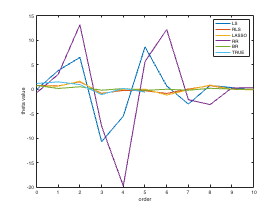

theta_order = [theta_LS, theta_RLS, theta_LASSO, theta_RR, mean_BR];
order = 0:10;
plot(order, theta_order);
xlabel("order");
ylabel("theta value");
hold on
plot(0:5, thtrue);
hold off
legend(["LS", "RLS", "LASSO", "RR", "BR", "TRUE"]);